clear, clc
load('mitdb_dataset.mat')
%ecg_mit = ecg;
Fs_mit = Fs;
%rr_mit = rr;
%rr_tm_mit = rr_tm; 
tm_mit = tm;
rrInterval = cell(23,1);

qrs_amp_raw = cell(23,1);
rr_tm_mit = cell(23,1);
delay = cell(23,1);

for i = 1:23 % DEPENDENCY ON TOOLBOX CONTAINING PAN_TOMPKIN2
    [qrs_amp_raw{i,1},rr_tm_mit{i,1},delay{i,1}] = pan_tompkin2(ecg{i,1},Fs_mit(i));
    rrInterval{i,1} = zeros(1,length(rr_tm_mit{i,1})-1);
    for z = 1:length(rrInterval{i,1})-1
        rrInterval{i,1}(z) = rr_tm_mit{i,1}(z+1) - rr_tm_mit{i,1}(z);
    end
end

[noisy1_12, targNoiseSigma1_1] = createSignalPlusNoise(ecg{1,1},12);
[noisy1_6, ~] = createSignalPlusNoise(ecg{1,1},6);
[noisy4_12, ~] = createSignalPlusNoise(ecg{4,1},12);
[noisy4_6, ~] = createSignalPlusNoise(ecg{4,1},6);

recNum = 4; % Can select number between 1 and 23 to access MIT database
%ecgRecord = ecg_mit{recNum,1}'; % Accesses the desired ECG signal
ecgRecord = noisy4_6;
theseRRintervals = rrInterval{recNum,1}; % 
medianSegLength = median(theseRRintervals);
mu_moving = movmean(ecgRecord,medianSegLength/2);
data = ecgRecord - mu_moving;
%n = length(data);
rPeakStamps = rr_tm_mit{recNum,1};
%numSegments = length(rPeakStamps);
numSegments = 400;

segmentLength = medianSegLength + ceil(medianSegLength /2);
segments = nan(numSegments,segmentLength);
startstopIndices = zeros(2,numSegments);
ecgStart = 1;
ecgEnd = rPeakStamps(1) + floor((rPeakStamps(2) - rPeakStamps(1))/2);
ecgLength = ecgEnd - ecgStart + 1;
delta = segmentLength - ecgLength;
segment = data(ecgStart:ecgEnd);
segStart = floor(delta/2);
segEnd = segmentLength - ceil(delta/2) - 1;
%segment(floor(delta/2)+1:segmentLength-ceil(delta/2)) = data(ecgStart:ecgEnd);
startstopIndices(:,1) = [segStart;segEnd];
segments(1,segStart:segEnd) = segment;



for i = 2:numSegments-1
    segment = [];
    %end_index = rPeakStamps(i) + ceil(segmentLength/2) - 1;
    ecgStart = ecgEnd+1;
    %ecgEnd = rPeakStamps(i) + floor((rPeakStamps(i+1)-rPeakStamps(i))/2) ;
    ecgEnd = rPeakStamps(i) + ceil((rPeakStamps(i+1) - rPeakStamps(i))/2);
    ecgLength = ecgEnd - ecgStart + 1;
    delta = segmentLength - ecgLength;
    segment = data(ecgStart:ecgEnd);
    segStart = floor(delta/2);
    segEnd = segmentLength - ceil(delta/2) - 1;
    startstopIndices(:,i) = [segStart;segEnd];
    segments(i, segStart:segEnd) = segment;
end

i = i+1;
ecgStart = ecgEnd+1;
ecgEnd = rPeakStamps(i) + ceil((rPeakStamps(i+1) - rPeakStamps(i))/2);
%ecgEnd = n;
ecgLength = ecgEnd - ecgStart + 1;
delta = segmentLength - ecgLength;
segment = data(ecgStart:ecgEnd);
segStart = floor(delta/2);
segEnd = segmentLength - ceil(delta/2) - 1;
startstopIndices(:,end) = [segStart;segEnd];
segments(end,segStart : segEnd) = segment;





row_means = mean(segments,2,'omitnan');
X_centered = segments - row_means;
segments2 = fillmissing(X_centered,'constant',0);
[centeredSegments, refTimes] = ecgsCentered(segments2,startstopIndices);


[Y_pca,score,latent,tsquared,explained,mu] = pca(centeredSegments);

P=1;
pcaDenoised = score(:,1:P) * Y_pca(:,1:P)' + row_means + mu;

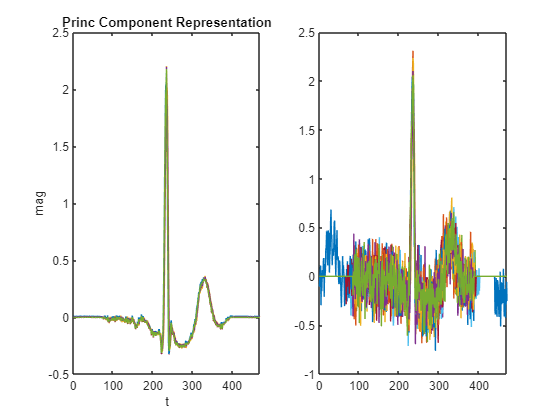

figure()
subplot(1,2,1)
plot(1:segmentLength,pcaDenoised(1:12,:))
xlabel('t')
ylabel('mag')
title('Princ Component Representation')
subplot(1,2,2)
plot(1:segmentLength,centeredSegments(1:12,:))

sigDenoised = [];
for i = 1:numSegments
    segStart = startstopIndices(1,i);
    segEnd = startstopIndices(2,i);
    sigDenoised = [sigDenoised, pcaDenoised(i,segStart:segEnd)];
end
n=length(sigDenoised);
sigDenoised = sigDenoised + mu_moving(1:n)';

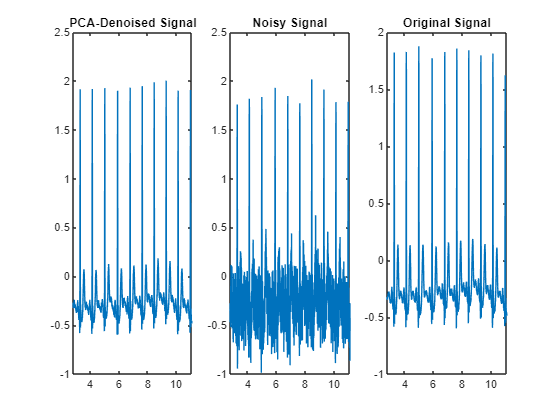

sampInterval2Plot = 1001:4000;
timeInterval2Plot = tm{recNum,1}(sampInterval2Plot);
figure
subplot(1,3,1)
plot(timeInterval2Plot,sigDenoised(sampInterval2Plot))
title('PCA-Denoised Signal')
subplot(1,3,2)
plot(timeInterval2Plot,ecgRecord(sampInterval2Plot))
title('Noisy Signal')
subplot(1,3,3)
plot(timeInterval2Plot,ecg{recNum,1}(sampInterval2Plot))
title('Original Signal')

%Compare Denoised Signal to Ground Truth
delta = abs(sigDenoised - ecg{recNum,1}(1:length(sigDenoised))');

%Compare Ground Truth to Noisy Signal
deltaNoise = abs(ecg{recNum,1}(1:length(sigDenoised)) - ecgRecord(1:length(sigDenoised)));
deltaSquare = delta.^2;
deltaNoiseSquare = deltaNoise.^2;
MSE = 1/length(sigDenoised) * sum(deltaSquare);
MAE = 1/length(sigDenoised) * sum(delta);
MSE_noise = 1/length(sigDenoised) * sum(deltaNoiseSquare);
MAE_noise = 1/length(sigDenoised) * sum(deltaNoise);
disp(MSE)

    0.0406



disp(MAE)

    0.0656



disp(MSE_noise)

    0.0261



disp(MAE_noise)

    0.1288



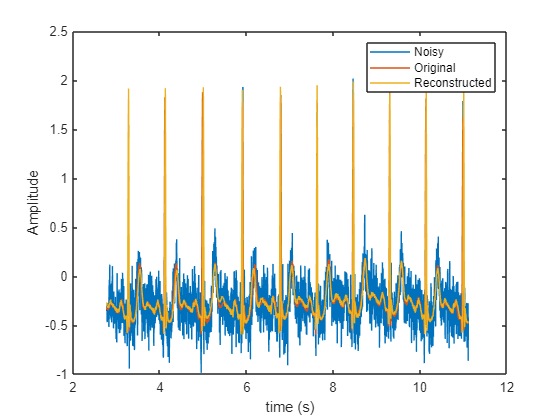


figure
plot(timeInterval2Plot,ecgRecord(sampInterval2Plot))
hold on
plot(timeInterval2Plot,ecg{recNum,1}(sampInterval2Plot))
plot(timeInterval2Plot,sigDenoised(sampInterval2Plot))
xlabel('time (s)')
ylabel('Amplitude')
legend('Noisy','Original','Reconstructed')